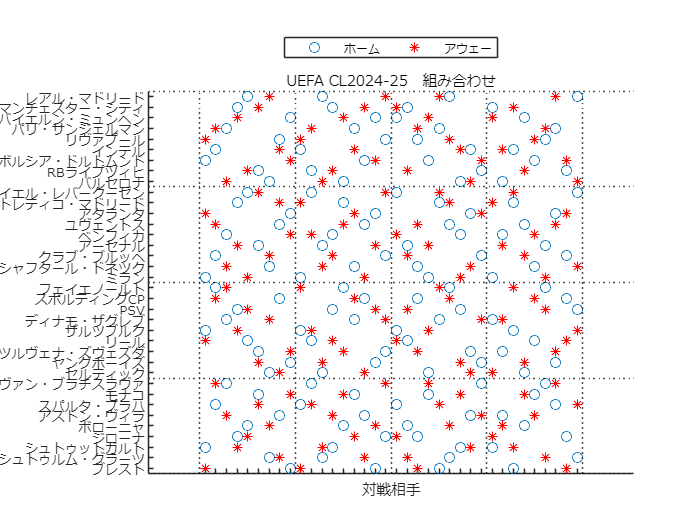

clear;
clc;
close all;

tbl=readtable("../data/UEFACL202425.xlsx", ...
    "VariableNamingRule","preserve");
tbl_teams=readtable("../data/UEFACL202425.xlsx", ...
    'Sheet','Sheet2','VariableNamingRule','preserve');
tbl_teams.("クラブ")=categorical(tbl_teams.("クラブ"));
tbl_teams.("国")=categorical(tbl_teams.("国"));

tbl.("クラブ")=categorical(tbl.("クラブ"));
tbl.Pot1Home=categorical(tbl.Pot1Home);
tbl.Pot1Away=categorical(tbl.Pot1Away);
tbl.Pot2Home=categorical(tbl.Pot2Home);
tbl.Pot2Away=categorical(tbl.Pot2Away);
tbl.Pot3Home=categorical(tbl.Pot3Home);
tbl.Pot3Away=categorical(tbl.Pot3Away);
tbl.Pot4Home=categorical(tbl.Pot4Home);
tbl.Pot4Away=categorical(tbl.Pot4Away);

outMat=[];
G=graph();

for n1=1:size(tbl_teams,1)
    ind=find(ismember(tbl_teams.("クラブ"), ...
        [tbl.Pot1Home(n1); ...
        tbl.Pot2Home(n1); ...
        tbl.Pot3Home(n1); ...
        tbl.Pot4Home(n1)]));
    outMat=[outMat;n1*ones(size(ind)) ind];
    G=G.addedge(n1,ind);

    ind=find(ismember(tbl_teams.("クラブ"), ...
        [tbl.Pot1Away(n1); ...
        tbl.Pot2Away(n1); ...
        tbl.Pot3Away(n1); ...
        tbl.Pot4Away(n1)]));
    outMat=[outMat;ind n1*ones(size(ind))];
end

figure
axis equal;hold on;
scatter(outMat(:,1),outMat(:,2));
scatter(outMat(:,2),outMat(:,1),'r*');
set(gca,'fontname','メイリオ','ydir','reverse','fontsize',8);
for n1=0.5:9:37
    xline(n1,'k:');
    yline(n1,'k:');
end
yticks(1:size(tbl_teams,1));
yticklabels(tbl_teams.("クラブ"));
xticks(1:size(tbl_teams,1));
xticklabels([]);
xlabel('対戦相手');
legend({'ホーム','アウェー'},'Location','northoutside','Orientation','horizontal');
title('UEFA CL2024-25　組み合わせ');
exportgraphics(gcf,'fig_UEFACL2024-25_GL.pdf');

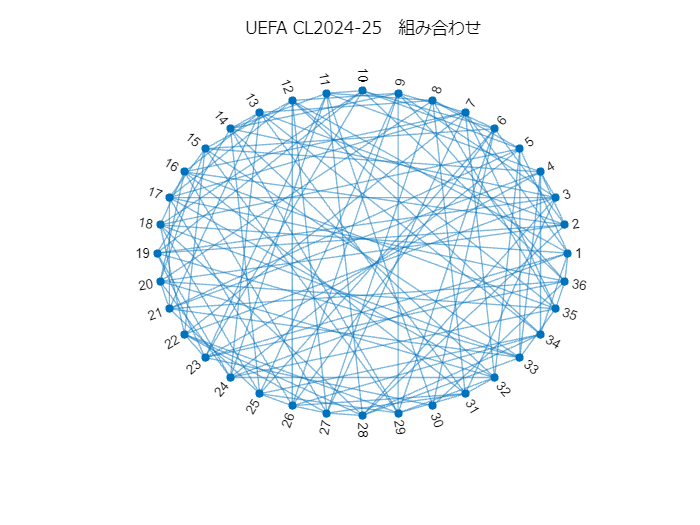


figure
title('UEFA CL2024-25　組み合わせ');hold on;
set(gca,'fontname','メイリオ','XColor','none','YColor','none');
plot(G,'Layout','circle');xticklabels([]);yticklabels([]);
exportgraphics(gcf,'fig_UEFACL2024-25_GL_graph.pdf');